# interpolation and extrapolation

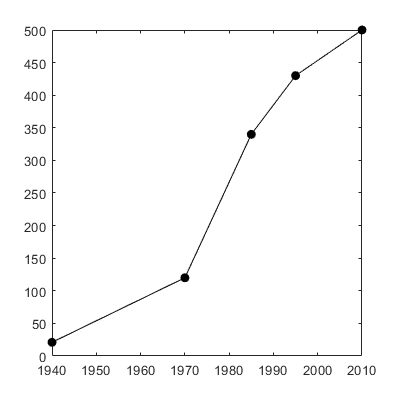

% tiger population
t_pop = [21 120 340 430 500];
year = [1940 1970 1985 1995 2010];
plot(year, t_pop, '-ok', 'MarkerFaceColor', 'k')

ti = [1960 2000];
te = [1935 2012];
y_interpolated = interp1(year, t_pop, ti, 'cubic');

y_extrapolated = interp1(year, t_pop, te, 'cubic', 'extrap');

y_interpolated, y_extrapolated

y_interpolated =    68.5772  459.8053


y_extrapolated =    24.5325  503.1415


# arrhenius

Ea = fzero('8.7e-14 - 1.3*exp(-x/(8.314*310))', 1e4)